# Trajectory Generation

## Load the map

map = load('trajectories/complexmap2.mat');

map = map.complexMap;
map

map = 41×52 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0  

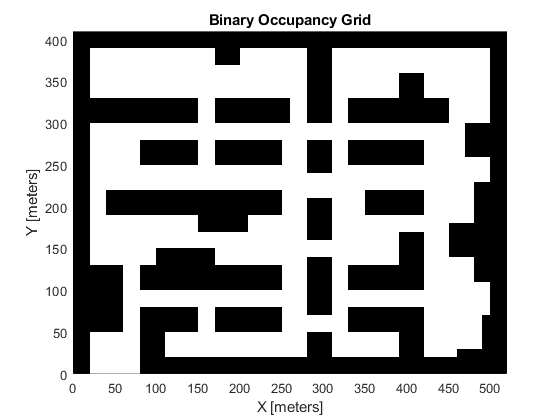

Resolution=.1; % meters
map = binaryOccupancyMap(map,Resolution);
map = binaryOccupancyMap(map);
uavRadius = 2.0;

% inflate map
inflate(map,uavRadius);
show(map)

## Create waypoints

start = [50 25];

p1 = [150 90];
p2 = [130 180];
p3 = [260 40];
p4 = [350 155];
p5 = [325 300];
p6 = [200 360];
p7 = [80 290];
p8 = [160 380];
p9 = [300 290];
p10 = [40 140];
p11 = [325 160];
p12 = [450 50];
p13 = [200 230];
p14 = [440 210];
p15 = [260 275];
p16 = [300 60];
p17 = [390 370];
p18 = [400 240];
p19 = [110 240];
p20 = [260 140];
waypoints = [p1; p2; p3; p4; p5; p6; p7; p8; p9; p10; p11; p12; p13; p14; p15; p16; p17; p18; p19; p20]

waypoints =    150    90
   130   180
   260    40
   350   155
   325   300
   200   360
    80   290
   160   380
   300   290
    40   140



%waypoints = [p10; p2; p15; p14; p12;]
%waypoints = [p1; p2; p3; p4];
%waypoints = [p1; p3; p4; p5; p6];
%waypoints = [p1; p10; p7; p8; p9];
% waypoints = [[150 150]; ...
%              [50 275]; ...
%              [150 400]; ...
%              [50 525]; ...
%              [150 650]; ...
%              [50 800]; ...
%              [150 900] ...
%              [50 1000]; ...
%              [150 1150]; ...
%              [50 1250]; ...
%              [150 1375]; ...
%              [50 1500]];
%waypoints = [p20; p8; p9]
waypoints = [p11; p18; p8]

waypoints =    325   160
   400   240
   160   380


%waypoints = [p19; p6; p9; p11; p20]
%waypoints = [p1; p3; p16; p4; p18; p17]

## Visualize map and waypoints

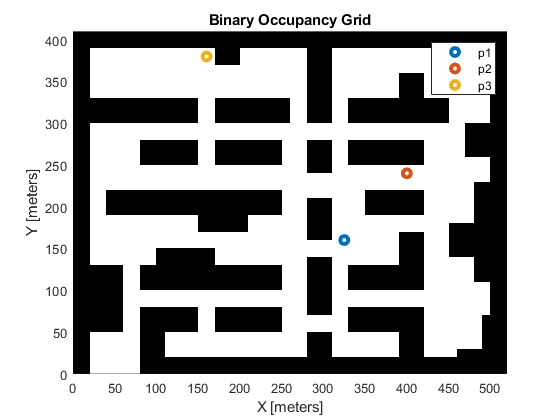

f1 = figure(1); clf;
hold on;
show(map);
%plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
%for i = 1:length(trajectory.x_waypoints)
 %   plot(trajectory.x_waypoints(i), trajectory.y_waypoints(i), 'o', 'LineWidth', 3)
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3, 'DisplayName', sprintf("p%d", i)); 
end
hold off;
legend;

%plot(trajectory.start(1), trajectory.start(2), 'rx', 'MarkerFaceColor', 'green', 'linewidth', 3);


## Build PRM

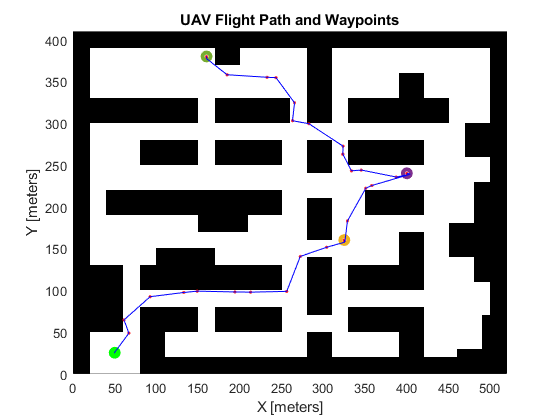

prm = mobileRobotPRM;
prm.Map = map;

prm.NumNodes = 1000;
prm.ConnectionDistance = 50;

path = findpath(prm, start, waypoints(1,:));
for i = 2:length(waypoints(:,1))
   p = findpath(prm, waypoints(i-1,:), waypoints(i,:));
   path = [path; p];
end
f2 = figure(2); clf;
hold on;
show(map);
plot(path(:,1), path(:,2), 'r.', 'MarkerSize', 5)
plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(path-1)
    plot([path(i-1,1) path(i, 1)], [path(i-1,2) path(i, 2)], 'b');
end
hold off;
title("UAV Flight Path and Waypoints")

## Calculate flight parameters

desiredVelocity = 1; % m/s
path_distance = calculatedistance(path); % total distance to be covered
time_interval = calculatetime(path_distance,desiredVelocity); 
stoptimetotal = time_interval(2); % time to complete the mission
% generate smooth time stamped trajectory
sampletimetraj=1; % 0.5 seconds by default
tSamples = sampletimetraj:sampletimetraj:time_interval(2);
[q,qd,qdd,pp] = bsplinepolytraj(path',time_interval,tSamples);
x_ref_points = [tSamples',q(1,:)'];
y_ref_points = [tSamples',q(2,:)'];
path_time = stoptimetotal/60;

## Write trajectory data to db

% the database connection
conn = db_connect('nasadb');
write_trajectory_data(conn, start, path_distance, path_time, waypoints);
conn.close();
clear conn;


## Load trajectory data

- Trajectories were loaded to a csv file from the database first

%trajectory_tb = sqlread(conn, 'trajectory_tb');
trajectory_tb = readtable('trajectories/trajectories_jss.csv');
max_flight_time = 30.0;

trajectory_tb = trajectory_tb(trajectory_tb.path_time < max_flight_time, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend')

trajectory_tb = 8×13 table
    id    path_distance    path_time    risk_factor         start            destination                      x_waypoints                                y_waypoints                  x_ref_points    y_ref_points    sample_time    reward      map  
    __    _____________    _________    ___________    _______________    _________________    _________________________________________    ______________________________________    ____________    ____________    ___________    ______    _______

    17       880.81          14.68  